%%% Define baseline parameters:
rho_outer = 0.08;
rho_inner = 0.015;

% Actuator position radii and the associated moment-arm matrix
rhos = [-rho_outer, -rho_inner, rho_inner, rho_outer];
mat_A = [
    1, 1, 1, 1;
    0, 0, 0, 0;
    -rhos;
    ];

l_0 = 0.5;

g_0 = Pose2.hat([0, 0, -pi/2]);
N_nodes = 10;

% Assemble it all into structs
struct_design_base = struct();
struct_design_base.mat_A = mat_A;
struct_design_base.rhos = rhos;
struct_design_base.l_0 = l_0;
struct_design_base.g_0 = g_0;

% Muscle force functions
f_bellow = @JacobBellowMechanics.actuator_force;
f_muscle = @GinaMuscleMechanics.actuatorForce_key;

%%% Create variations 
struct_antagonist = struct_design_base;
struct_antagonist.fs = {f_bellow, f_muscle, f_muscle, f_bellow};
struct_antagonist.p_bounds = [50; 100; 100; 50];

struct_4muscle= struct_design_base;
struct_4muscle.fs = {f_muscle, f_muscle, f_muscle, f_muscle};
struct_4muscle.p_bounds = [100; 100; 100; 100];

struct_4bellow= struct_design_base;
struct_4bellow.fs = {f_bellow, f_bellow, f_bellow, f_bellow};
struct_4bellow.p_bounds = [50; 50; 50; 50];

arm_designs = {struct_4bellow, struct_antagonist};
N_designs = numel(arm_designs);

%%% Generate the test shape

f_affine_curvature = @(s, a, b) [
    l_0*ones(size(s)); % TODO: This seems suspect - but for these tests it's really hard to consider what this should be
    zeros(size(s));
    a*s + b
];

s = linspace(0, 1, N_nodes);
segment_twists = f_affine_curvature(s, -3, 3);

%%% Compute the attainable wrench space
cell_bndries_af = cell(1, N_designs);
cell_bndries_am = cell(1, N_designs);

for i = 1 : N_designs
    [cell_bndries_af{i}, cell_bndries_am{i}] = calc_attainable_wrench_hull(segment_twists, arm_designs{i});
end

%%% Sample external loads and compute the corresponding externally-induced
%%% wrenches
% First we generate the tip loads
F_x_scale = 20;
F_y_scale = 20;
tau_scale = 2;
K_scales = diag([F_x_scale, F_y_scale, tau_scale]);

rng(100);
N_test_ws = 20;
w_tip_tests = K_scales* (rand(3, N_test_ws) - 0.5);
mat_s_w_samples = repmat(s, [N_test_ws, 1]);

% For each tip load, compute the corresponding loads that they induce 
% at each point along the lengths of each above arm

all_a_req_traces_f = zeros(N_nodes, N_test_ws);
all_a_req_traces_m = zeros(N_nodes, N_test_ws);

ws= zeros(3, N_nodes, N_test_ws);
    
for i_test = 1 : N_test_ws
    w_tip_i = w_tip_tests(:, i_test);
    ws(:, :, i_test) = calc_external_wrench(segment_twists, w_tip_i, g_0);
end
    
[all_a_req_traces_f, all_a_req_traces_m] = mat_wrenches_to_traces(-ws);

%%% For each arm design: for each tip load, find the attainable arm shape
%%% that is closest to the target shape
min_residuals_all = zeros(N_designs, N_test_ws);
p_solns = zeros(4, N_test_ws, N_designs);

tic
f = waitbar(0, "Finding optimal pressures for...");
total = N_designs * N_test_ws;
for i_design = 1 : N_designs
    design_to_test = arm_designs{i_design};

    for i_load = 1 : N_test_ws
        progress = (i_design-1)*N_test_ws + i_load;
        wait_text = sprintf("Finding optimal pressures for arm %d load %d [%d/%d]", i_design, i_load, progress, total);
        waitbar(progress/total, f, wait_text)

        w_tip_i = w_tip_tests(:, i_load);
        p_0 = [10; 0; 10; 0];
        p_solns(:, i_load, i_design) = find_p_minimize_pose_error(segment_twists, w_tip_i, design_to_test, p_0=p_0);
    end
end


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Local minimum found that satisfies the constraints.

Optimization completed because the objective fu


Feasible point with lower objective function value found, but optimality criteria not satisfied. See output.bestfeasible..


Local minimum possible. Constraints satisfied.

fmincon stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>

<a href 

dt_naive = toc

dt = 8.7661e+03

waitbar(1, f, sprintf("Completed after %.2f", dt));

Error using waitbar (line 111)
The second argument must be a message character vector or a handle to an existing waitbar.

figure(f)

tic
abs_attainability = zeros(N_designs, N_test_ws);
K = [0.01, 1];

f = waitbar(0, "Computing absolute attainability for...");
for i_design = 1 : N_designs
    design_to_test = arm_designs{i_design};

    for i_load = 1 : N_test_ws
        w_tip_i = w_tip_tests(:, i_load);
        abs_attainability(i_design, i_load) = calc_abs_attainability_metric(segment_twists, w_tip_i, design_to_test, K);
        
        wait_text = sprintf("Computing absolute attainability for arm %d load %d [%d/%d]", i_design, i_load, progress, total);
        progress = (i_design-1)*N_test_ws + i_load;
        waitbar(progress/total, f, wait_text)
    end
end
dt_attnblty = toc

dt_attnblty = 71.4616

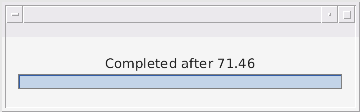

waitbar(1, f, sprintf("Completed after %.2f", dt_attnblty));

figure(f)

% Compute all of the equilibrium poses from the above arm designs and test
% loads. Afterwards we can just directly index from here and skip the
% hassel
tic
cell_closest_poses = cell(N_designs, N_test_ws);
cell_closest_twists = cell(N_designs, N_test_ws);
residuals = zeros(N_designs, N_test_ws);

for i_design = 1 : N_designs
    for i_load = 1 : N_test_ws
        [cell_closest_twists{i_design, i_load}, mat_res_i] = ...
            solve_equilibrium_shape(N_nodes, arm_designs{i_design}, p_solns(:, i_load, i_design), w_tip_tests(:, i_load));
        residuals(i_design, i_load) = norm(mat_res_i);

        cell_closest_poses{i_design, i_load} = calc_poses(g_0, cell_closest_twists{i_design, i_load});
    end
end
toc

Elapsed time is 43.308623 seconds.


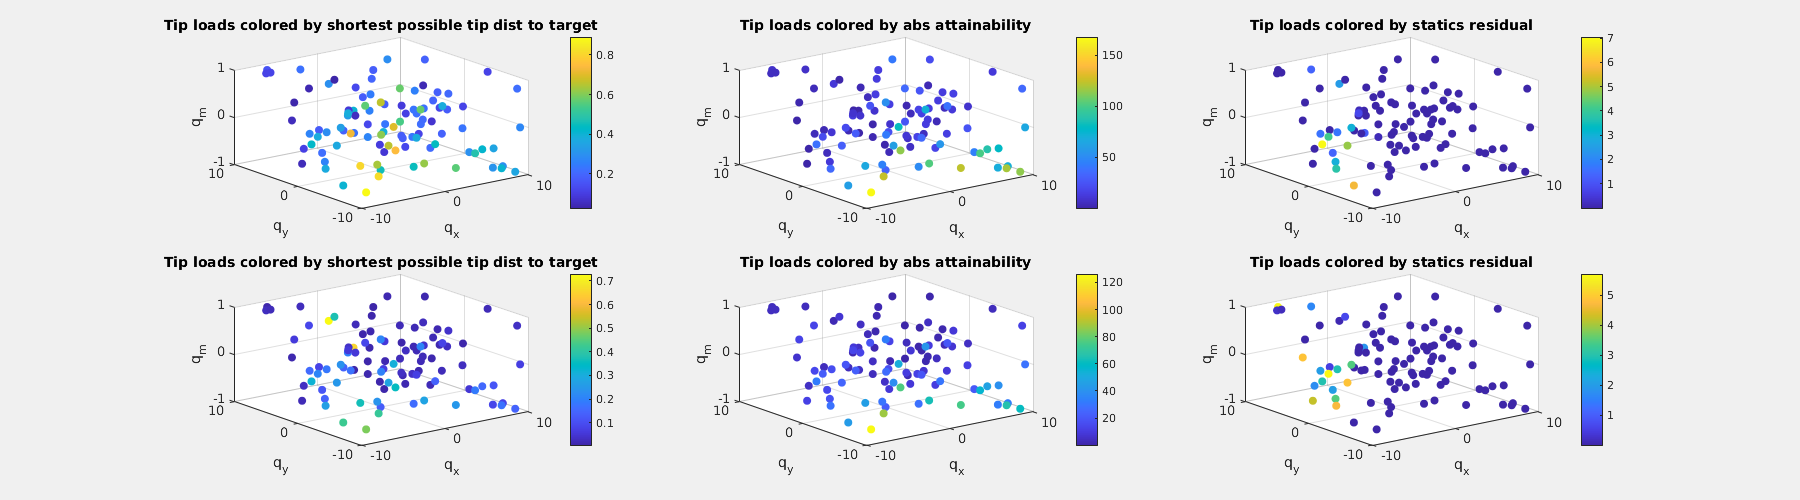

% Find the weirdos
figure("visible", true, "Position", [0, 0, 1800, 500]);

mat_tip_poses = zeros(3, N_test_ws, 2);
cell_diffs = cell(1, 2);
for i_design = 1:2
    tip_poses = cellfun(@(C) Pose2.vee(C(:, :, end)), cell_closest_poses(i_design, :), 'UniformOutput', false);
    tip_poses = [tip_poses{1, :}];
    poses_target = calc_poses(g_0, segment_twists);
    tip_pose_target = poses_target(:, :, end);
    
    diffs = tip_poses - Pose2.vee(tip_pose_target);
    mat_tip_poses(:, :, i_design) = tip_poses;
    cell_diffs{i_design} = diffs;
    
    % Sort pressures/loads by their associated tip position errors
    [~, i_sort] = sort(vecnorm(diffs(1:2, :)));

    subplot(2, 3, (i_design-1)*3 + 1)
    scatter3(w_tip_tests(1, :), w_tip_tests(2, :), w_tip_tests(3, :), [], vecnorm(diffs(1:2, :)), "filled");
    title("Tip loads colored by shortest possible tip dist to target")
    colorbar
    xlabel("q_x")
    ylabel("q_y")
    zlabel("q_m")
    
    subplot(2, 3, (i_design-1)*3 + 2)
    scatter3(w_tip_tests(1, :), w_tip_tests(2, :), w_tip_tests(3, :), [], abs_attainability(i_design, :), "filled");
    colorbar
    xlabel("q_x")
    ylabel("q_y")
    zlabel("q_m")
    title("Tip loads colored by abs attainability")
    
    subplot(2, 3, (i_design-1)*3 + 3)
    scatter3(w_tip_tests(1, :), w_tip_tests(2, :), w_tip_tests(3, :), [], residuals(i_design, :), "filled");
    xlabel("q_x")
    ylabel("q_y")
    zlabel("q_m")
    title("Tip loads colored by statics residual")
    colorbar
end

% Identify the tip loads for which one of the two arms' static equilibrium
% solver did not converge. We will discard the tip loads, as well as the 
% associated solution pressure, twists, and poses. 

i_converged = all(residuals < 1e-5, 1);

p_solns_convgd = p_solns(:, i_converged);
w_tip_tests_convgd = w_tip_tests(:, i_converged);
abs_unattainability_convgd = abs_attainability(:, i_converged);
cell_closest_twists_convgd = cell_closest_twists(:, i_converged);
cell_closest_poses_convgd = cell_closest_poses(:, i_converged);
mat_tip_poses_convgd = mat_tip_poses(:, i_converged, :);

N_qs_converged = sum(i_converged);

## PLOTTING

color_green = [45 182 125] / 255;
color_yellow = [255 176 0] / 255;
color_blue = [100 143 255] / 255;
color_red = [255 48 150] / 255;
colors = [color_red; color_blue; color_yellow];

% Lighter colors
colors_light_green = [130 205 174] / 255;
colors_light_yellow = [248 203 97] / 255;
colors_light_blue = [135 167 250] / 255;
colors_light_red = [230 100 164] / 255;
colors_light = [colors_light_red; colors_light_blue; colors_light_yellow];

% Darker colors
color_dark_green = [0.0706    0.5137    0.3294];
color_dark_blue = [0.2941    0.4196    0.7490];
color_dark_yellow = [0.7490    0.5176         0];
color_dark_red = [0.6549    0.1059    0.3725];
colors_dark = [color_dark_red; color_dark_blue; color_dark_yellow];

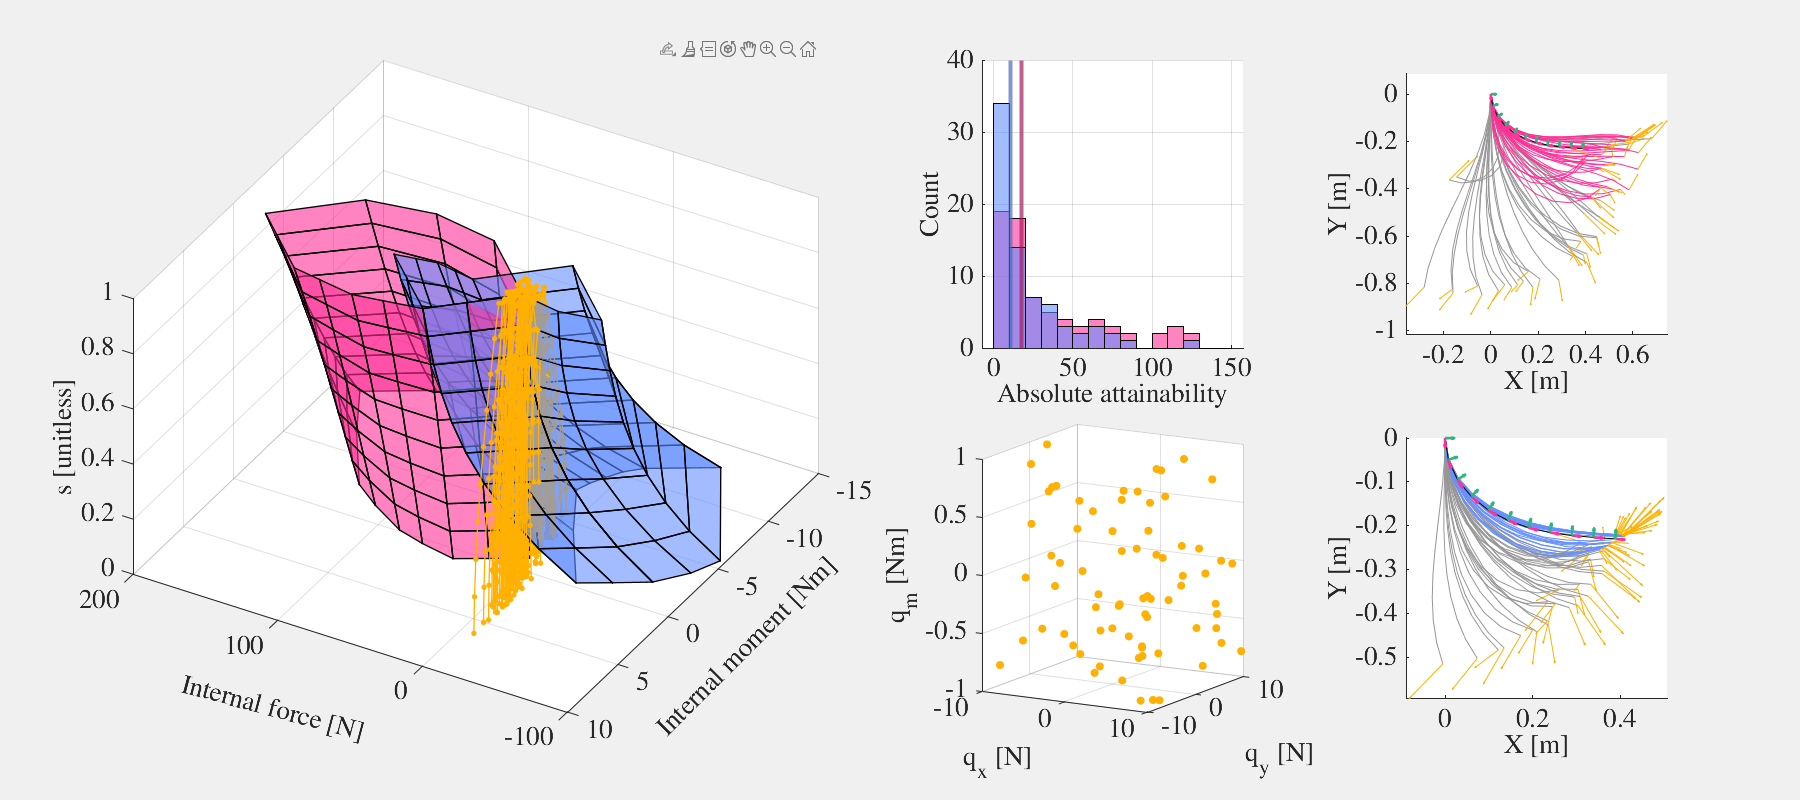

figure("Visible", true, "Position", [0, 0, 1800, 800])
t = tiledlayout(2, 4, "TileIndexing", "columnmajor", "Tilespacing", "compact");

% Plot 1: Comparison of the attainable wrench hulls of the bellows-only and
% antagonistic designs.
ax = nexttile([2, 2]);
hold on
for i = 1 : N_designs
    plot_wrench_hull(cell_bndries_af{i}, cell_bndries_am{i}, ax, colors(i, :));
end
plot3(all_a_req_traces_f, all_a_req_traces_m, mat_s_w_samples', "o-", "color", color_yellow, "markerfacecolor", color_yellow, "markersize", 3, "linewidth", 1)
view(-150, 45);
grid on;
xlabel("Internal force [N]", "Rotation", -15)
ylabel("Internal moment [Nm]", "Position", [-114.772434145481,3.6260568700244,-0.236833573027585], "Rotation", 45)
zlabel("s [unitless]")

ax = nexttile([1, 1]);
hold on
median_unattainability = median(abs_unattainability_convgd, 2);
for i = 1 : N_designs
    histogram(abs_unattainability_convgd(i, :), 0:10:150,"facecolor", colors(i, :))
    xline(median_unattainability(i), "color", colors_dark(i, :), "linewidth", 3);
end
xlabel("Absolute attainability")
ylabel("Count")
grid on

ax = nexttile([1, 1]);

hold on
scatter3(w_tip_tests_convgd(1, :), w_tip_tests_convgd(2, :), w_tip_tests_convgd(3,:), [], color_yellow, "filled");
view(30, 10);
grid on
xlabel("q_x [N]")
ylabel("q_y [N]")
zlabel("q_m [Nm]")

ax_bellow_arm = nexttile([1, 1]);
hold on
poses_target = calc_poses(g_0, segment_twists);
[~, i_sort_1] = sort(attainability_of_loads(1, :), "descend");

% Plot solutions that converged in color
for i = find(abs_unattainability_convgd(1, :) > median_unattainability(1))
    closest_poses = cell_closest_poses_convgd{1, i};
    tip_pose = Pose2.vee(closest_poses(:, :, end));

    plot_poses(closest_poses, ax_bellow_arm, struct("color", [150 150 150] / 255), false);
    
    uv = w_tip_tests_convgd(1:2, i) * 0.01;
    quiver(tip_pose(1), tip_pose(2), uv(1), uv(2), "color", color_yellow);
end
for i = find(abs_unattainability_convgd(1, :) <= median_unattainability(1))
    closest_poses = cell_closest_poses_convgd{1, i};
    tip_pose = Pose2.vee(closest_poses(:, :, end));

    plot_poses(closest_poses, ax_bellow_arm, struct("color", colors(1, :)), false);
    
    uv = w_tip_tests_convgd(1:2, i) * 0.01;
    quiver(tip_pose(1), tip_pose(2), uv(1), uv(2), "color", color_yellow);
end

plot_poses(poses_target, ax_bellow_arm);
xlabel("X [m]")
ylabel("Y [m]")


ax_antag_arm = nexttile([1, 1]);
hold on
for i = find(abs_unattainability_convgd(2, :) > median_unattainability(2))
    closest_poses = cell_closest_poses_convgd{2, i};
    tip_pose = Pose2.vee(closest_poses(:, :, end));

    plot_poses(closest_poses, ax_antag_arm, struct("color", [150 150 150] / 255), false);
    
    uv = w_tip_tests_convgd(1:2, i) * 0.01;
    quiver(tip_pose(1), tip_pose(2), uv(1), uv(2), "color", color_yellow);
end
for i = find(abs_unattainability_convgd(2, :) <= median_unattainability(2))
    closest_poses = cell_closest_poses_convgd{2, i};
    tip_pose = Pose2.vee(closest_poses(:, :, end));

    plot_poses(closest_poses, ax_antag_arm, struct("color", colors(2, :)), false);
    
    uv = w_tip_tests_convgd(1:2, i) * 0.01;
    quiver(tip_pose(1), tip_pose(2), uv(1), uv(2), "color", color_yellow);
end
plot_poses(poses_target, ax_antag_arm);
xlabel("X [m]")
ylabel("Y [m]")

%linkaxes([ax_bellow_arm, ax_antag_arm]);


fontname("Nimbus roman")
fontsize(20, "points")

i_design = 1;
mat_tip_poses = cellfun(@(C) Pose2.vee(C(:, :, end)), cell_closest_poses_convgd(i_design, :), 'UniformOutput', false);
tip_poses = [mat_tip_poses{:}];
tip_pose_diffs = tip_poses - Pose2.vee(poses_target(:, :, end));



function residuals_out = check_equilibrium_norm_modified(segment_twists, w_tip, pressure, struct_design)
    
    % I'm not sure why q_test is directly implemented as an
    % external-wrench-along-arm value, rather than just the tip wrench.
    %
    % Before tracking down why that is, I'm just going to work with a
    % modified version of the function here.

    residuals = check_equilibrium(segment_twists, w_tip, pressure, struct_design);

    weights_stretch_vs_bending = [1, 1, 10];
    weighted_residuals = diag(weights_stretch_vs_bending) * residuals;

    %dist = norm(weighted_residuals(:));
    residuals_out = sum(vecnorm(weighted_residuals, 1));
end

function [min_residuals, p_solns] = test_attainability_across_loads(tip_loads, segment_twists, struct_design)
    % Check if the reactions induced by a tip load are actually attainable by an arm
    % Inputs:
    %   - w_tip (3 x N_tests): wrench vector representing the tip load.
    %   - segment_twists (3 x N_segments): twist vector at each segment
    %   - struct_design (struct): standard arm design struct
    %   - p_bounds (N_actuators x 1): max pressures for each actuator
    %
    % Outputs:
    %   - v_attainable (N_test_points x 1): boolean vector indicating
    %   whether each test arm reaction requirements are attainable
    N_tests = size(tip_loads, 2);
    N_actuators = length(struct_design.p_bounds);

    min_residuals = zeros(N_tests, 1);
    p_solns = zeros(length(struct_design.p_bounds), N_tests);

    N_starts = 5;
    v_zero = zeros(N_actuators, 1);
    start_points = diag(struct_design.p_bounds) * rand([N_actuators, N_starts - 2]);
    start_points = [start_points, v_zero, struct_design.p_bounds];

    for i = 1 : N_tests
        % Define the cost function: for each pressure, find how close it
        % gets the reactions to those required.
        
        f_reaction_dist = @(pres) check_equilibrium_norm_modified(segment_twists, tip_loads(:, i), pres, struct_design);
        opts = optimoptions('fmincon', 'display', 'off', 'StepTolerance', 1e-20, 'FunctionTolerance', 1e-10); 

        % Solve the optimization problem
        p_soln_starts = zeros(N_actuators, N_starts);
        min_residuals_i = zeros(N_starts, 1);
        for i_start = 1 : N_starts
            p_start = start_points(:, i_start);
            [p_soln_starts(:, i_start), min_residuals_i(i_start), ~, output] = fmincon(f_reaction_dist, p_start, [], [], [], [], v_zero, struct_design.p_bounds, [], opts); 
        end

        % Of the result from each starting point, find the lowest one.
        [min_residuals(i), i_start_min] = min(min_residuals_i);
        p_solns(:, i) = p_soln_starts(:, i_start_min);
    end
end